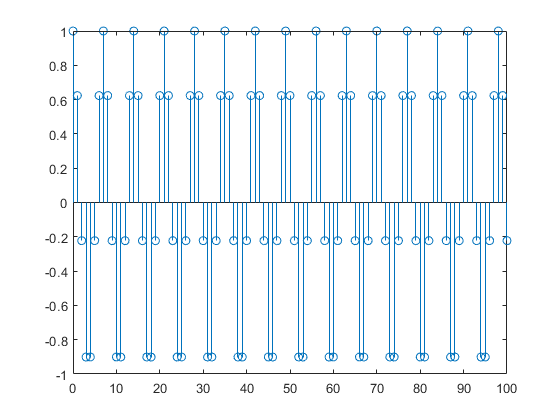

clear; close all; clc;
n = 0:100;
f = cos(30*pi*n / 105);
figure
stem(n,f)

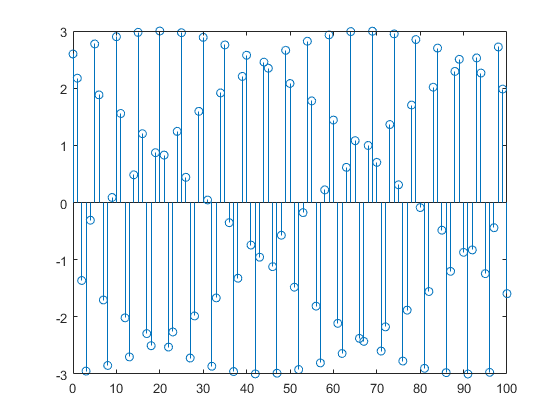

figure
f2 = 3 * cos(5 * n + pi/6);
stem(n,f2)

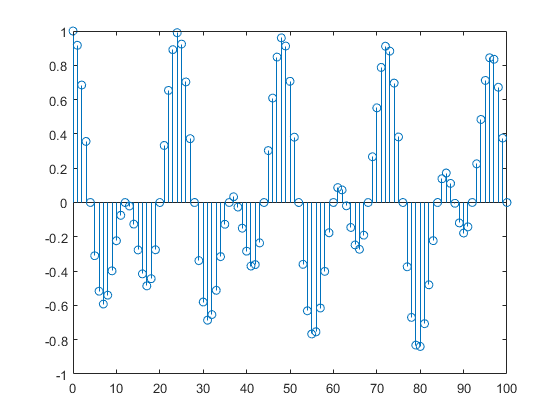


figure
f3 = cos(n / 8) .* cos(pi * n / 8);
stem(n,f3)

t = 0:0.01:1;
fo = 3 * cos(100 * pi * t) + 2 * sin (250 * pi * t)

fo =     3.0000   -1.0000    3.0000   -5.0000    3.0000   -1.0000    3.0000   -5.0000    3.0000   -1.0000    3.0000   -5.0000    3.0000   -1.0000    3.0000   -5.0000    3.0000   -1.0000    3.0000   -5.0000    3.0000   -1.0000    3.0000   -5.0000    3.0000   -1.0000    3.0000   -5.0000    3.0000   -1.0000    3.0000   -5.0000    3.0000   -1.0000    3.0000   -5.0000    3.0000   -1.0000    3.0000   -5.0000    3.0000   -1.0000    3.0000   -5.0000    3.0000   -1.0000    3.0000   -5.0000    3.0000   -1.0000


Fp = 1 / (1e-3);
tx = t * Fp;
fx = 3 * cos(1/2 * pi * tx) + 2 * sin(-3/4 * pi * tx);
fx = 3 * cos(500 * pi * t)

fx =      3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3     3    -3


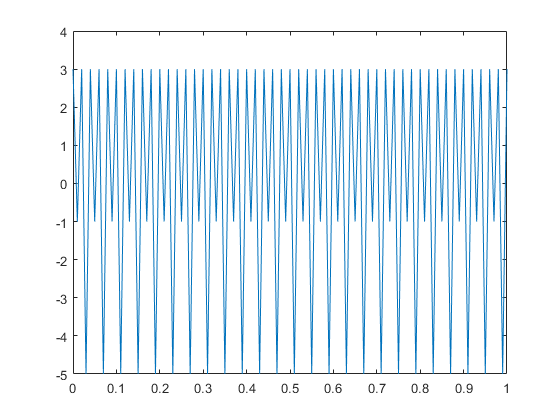


figure
plot(t, fo)

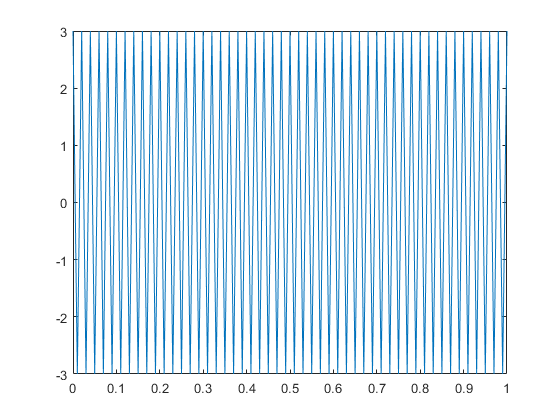

figure
plot(t, fx)

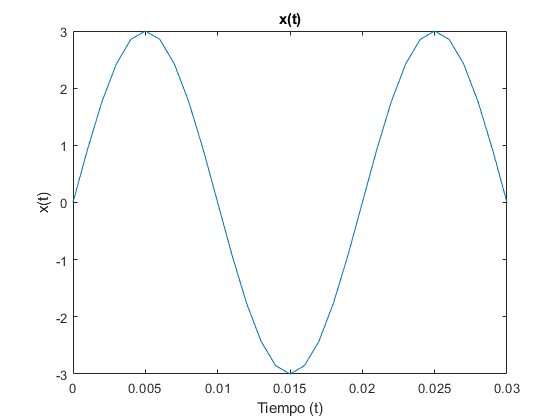

t5 = 0:0.001:(30 / 1000);
f5a = 3 * sin(100 * pi * t5);
figure
plot(t5, f5a)
title("x(t)")
xlabel("Tiempo (t)")
ylabel("x(t)")

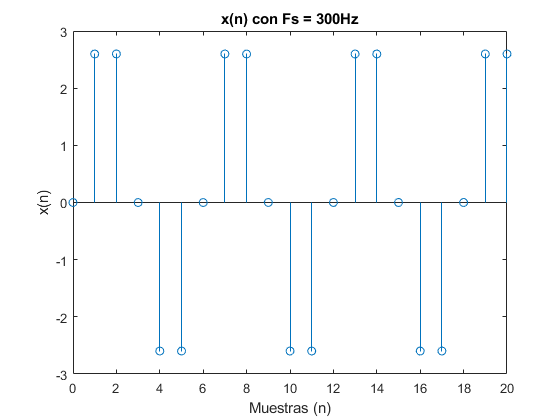

n5 = 0:20;
f5b = 3 * sin(pi/3 * n5);
figure
stem(n5, f5b)
title("x(n) con Fs = 300Hz")
xlabel("Muestras (n)")
ylabel("x(n)")

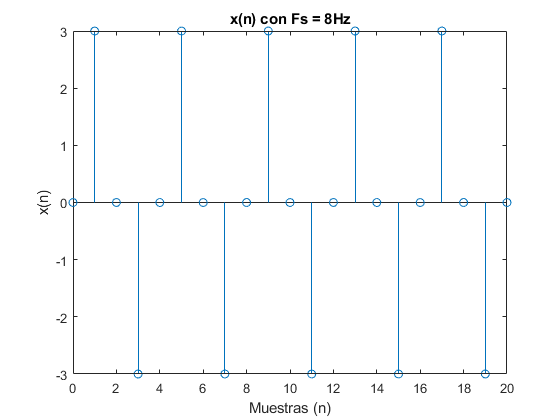

Fsd = 8;
f5d = 3 * sin(100 * pi * n5 / Fsd);
figure
stem(n5, f5d)
title("x(n) con Fs = 8Hz")
xlabel("Muestras (n)")
ylabel("x(n)")

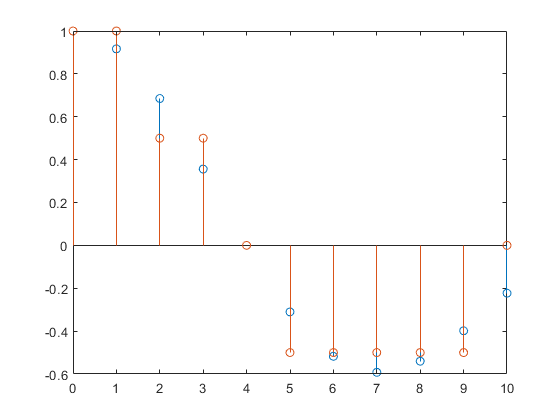

n = 0:10;
figure
f3 = cos(n / 8) .* cos(pi * n / 8);
stem(n,f3)

levels = 5;
quantizedR = quantizer(f3, levels, 1, 'rounding');
quantizedT = quantizer(f3, levels, 1, 'truncation');
hold on
stem(n, quantizedR)
hold off

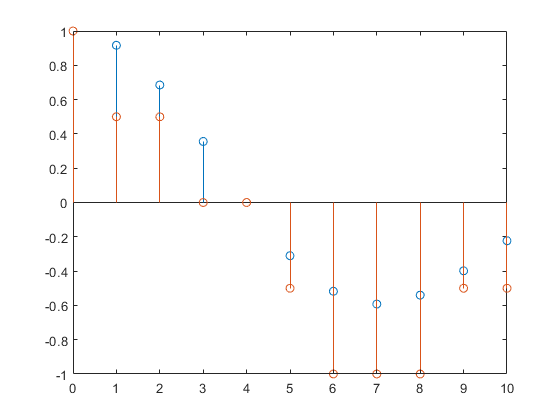


figure
stem(n, f3)
hold on
stem(n, quantizedT)

function quantizedSignal = quantizer(signal, levelsCount, expectedMax, type)
    levels = linspace(-expectedMax, expectedMax, levelsCount);
    quantizedSignal = zeros(1,length(signal));
    
    if strcmp(type, 'truncation')
        
        for i=1:length(signal)
            lesserValues = levels(levels <= signal(i));
            quantizedSignal(i) = lesserValues(end);
        end
        
    elseif strcmp(type, 'rounding')
        for i=1:length(signal)
            lesserValues = levels(levels <= signal(i));
            greaterValues = levels(levels >= signal(i));
            distanceBelow = signal(i) - lesserValues(end);
            distanceAbove = greaterValues(1) - signal(i);
            
            if distanceBelow <= distanceAbove
                quantizedSignal(i) = lesserValues(end);
            else
                quantizedSignal(i) = greaterValues(1);
            end
            
        end
        
    else
        error("Not a proper type of quantization")
    end
end